# **UE1 USRP B210  Receiver **

## Set OFDM Frame Parameters

clear;
% 第一部分可以认为是控制基站的功能
% The chosen set of OFDM parameters overall for all BSs:
overAllOfdmParams.online_BS               = 2;              % number of online data BS 
overAllOfdmParams.FFTLength               = 512;              % FFT length
overAllOfdmParams.CPLength                = ceil(overAllOfdmParams.FFTLength*0.25);   % Cyclic prefix length
overAllOfdmParams.PilotSubcarrierSpacing  = 36;                                 % Pilot sub-carrier spacing
total_RB                                  = 36;                                % User input Resource block number

% 调用calculateRBFinal函数确保最终的RB确定的子载波总数能够被pilot subcarrier spacing整除
[RB_verified, MaxRB] = calculateRBFinal(overAllOfdmParams, total_RB);
% 补充，其实新的算法不需要这个强限制，直接传入total RB即可

% check if RB_verified exceed MaxRB
if total_RB > MaxRB || RB_verified > MaxRB
    error('Error: Defined RB (%d) exceeds the system maximum allowed RB (%d). ', RB_verified, MaxRB);
end

overAllOfdmParams.total_RB                     = total_RB;
overAllOfdmParams.total_NumSubcarriers         = overAllOfdmParams.total_RB*12;                  % Number of sub-carriers in the band = resourceblock * 12 (must less than FFTlength)
overAllOfdmParams.guard_interval = (overAllOfdmParams.FFTLength - overAllOfdmParams.total_NumSubcarriers) / 2;     % Guard interval, 单侧的空载波
% check if NumSubcarriers less than FFTLength
if overAllOfdmParams.total_NumSubcarriers > overAllOfdmParams.FFTLength
    error('Total NumSubcarriers: (%d) exceeds Total FFTLength: (%d), which is not allowed. Please reduce the value of RB.', ...
        overAllOfdmParams.total_NumSubcarriers, overAllOfdmParams.FFTLength);
end


% 接下来是针对B210 UE的radio resource OFDM parametr 设置
Rcv_DL_CoopBSs_id                 = [1];                   %当前服务该用户的下行基站协作集
UE_id                             = 1;                    %当前UE的ID标识符
OFDMParams.BWPoffset              = 0;                    %当前基站的总带宽offset（单位/1个子载波）              
% 将部分total 全局参数赋给OFDMParam参数
OFDMParams.online_BS              = overAllOfdmParams.online_BS;                 % number of online data BS 
OFDMParams.Rcv_DL_CoopBSs_id                  = Rcv_DL_CoopBSs_id;                              % receive BS id information
OFDMParams.FFTLength              = overAllOfdmParams.FFTLength;                  % FFT length
OFDMParams.CPLength               = overAllOfdmParams.CPLength;                   % Cyclic prefix length
OFDMParams.PilotSubcarrierSpacing = overAllOfdmParams.PilotSubcarrierSpacing;     % Pilot sub-carrier spacing这里直接默认为全局配置，后续可以针对化修改，即每个基站的pilot间隔不一样
% 根据BS id计算基站分配到的无线频谱资源, calculate allocated radio resource
[alloc_RadioResource, all_radioResource]     = calculateBWPs(overAllOfdmParams, OFDMParams.Rcv_DL_CoopBSs_id, OFDMParams.BWPoffset);
OFDMParams.NumSubcarriers               = alloc_RadioResource.UsedSubcc;                 % Number of sub-carriers in the band = resourceblock * 12 (must less than FFTlength)
OFDMParams.subcarrier_start_index       = alloc_RadioResource.subcarrier_start_index;    % 对应分配的BWP子载波起始位置
OFDMParams.subcarrier_end_index         = alloc_RadioResource.subcarrier_end_index;      % 对应分配的BWP子载波结束位置
OFDMParams.subcarrier_center_offset     = alloc_RadioResource.subcarrier_center_offset;  % 对应分配的BWP子载波中心偏移（相对于DC子载波)
OFDMParams.BWPoffset     = alloc_RadioResource.BWPoffset;                                % 对应分配的BWP人为设置Offset
OFDMParams.Subcarrierspacing      = 30e3;                          % Sub-carrier spacing of 30 KHz
OFDMParams.guard_interval         = overAllOfdmParams.guard_interval;              % 基站使用带宽的保护间隔
OFDMParams.channelBW              = (OFDMParams.guard_interval+OFDMParams.NumSubcarriers)*OFDMParams.Subcarrierspacing;   % Bandwidth of the channel for filter to pass
OFDMParams.signalBW               = (2*OFDMParams.guard_interval+OFDMParams.NumSubcarriers)*OFDMParams.Subcarrierspacing;   % Bandwidth of the signal for filter to cut-off


% Data Parameters
dataParams.modOrder       = 64;   % Data modulation order
dataParams.coderate       = "1/2";   % Code rate
dataParams.numSymPerFrame = 30;   % Number of data symbols per frame
dataParams.numFrames      = 30;   % Number of frames to transmit
dataParams.enableScopes   = true;                    % Switch to enable or disable the visibility of scopes
dataParams.verbosity      = true;                    % Control to print the output diagnostics at each level of receiver processing
dataParams.printData      = true;                    % Control to print the output decoded data
dataParams.enableConst_measure = true;

## Initialize Receiver Parameters

radioDevice            = "B210";   % Choose radio device for reception
channelmapping         = 1;  % mutichannel or single channel selection
centerFrequency        = 2.5e9;  % Center Frequency
centerFrequency        = 2.7e9;
gain                   = 60;  % Set radio gain
gain                   = 55;
save_data              = false;
read_savedData         = false;

read_filename = 'saved_frameData_qam64_cooperateTRdebug.bb';            % read saved received data from specific filename         
save_filename = 'saved_frameData_qam64_cooperateTRdebug.bb';           % save receiving data to specific filename

[sysParam,txParam,transportBlk_bs1,transportBlk_bs2] = helperOFDMSetParamsSDR(OFDMParams,dataParams,all_radioResource);
sysParam.total_usedSubcc = overAllOfdmParams.total_NumSubcarriers;
sysParam.total_usedRB = overAllOfdmParams.total_RB;
sampleRate                       = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal
sysParam.enableTimescope = false;
sysParam.enableCFO = true;
sysParam.enableCPE = true;
sysParam.enableChest = true;
sysParam.enableHeaderCRCcheck = true;

if read_savedData
    bbr = comm.BasebandFileReader(read_filename, ...
    SamplesPerFrame=sysParam.txWaveformSize);
end
ofdmRx = helperGetRadioParams(sysParam,radioDevice,sampleRate,centerFrequency,gain,channelmapping);

Checking radio connections...


[radio,spectrumAnalyze,constDiag, timesink, constellation_measure] = helperGetRadioRxObj(ofdmRx);
% timesink = 1;
constDiag.ShowTrajectory = false;

## Execute Receiver Loop

#### Synchronization

#### Frequency Offset Estimation and Correction

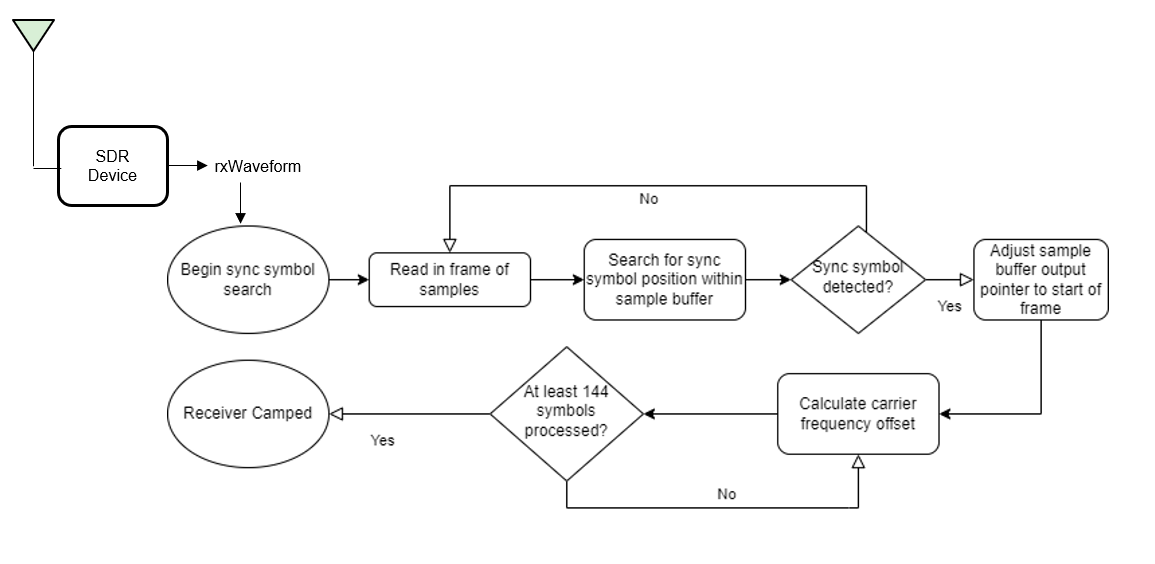

### Receiver Processing

#### Channel Estimation and Equalization

#### Header Decoding

#### Data Decoding

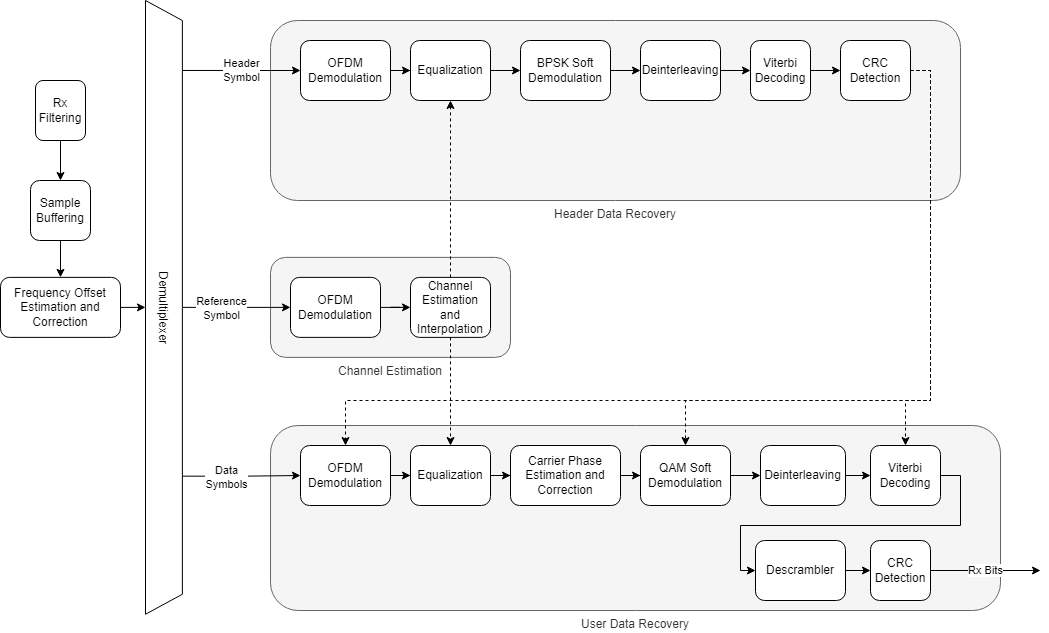

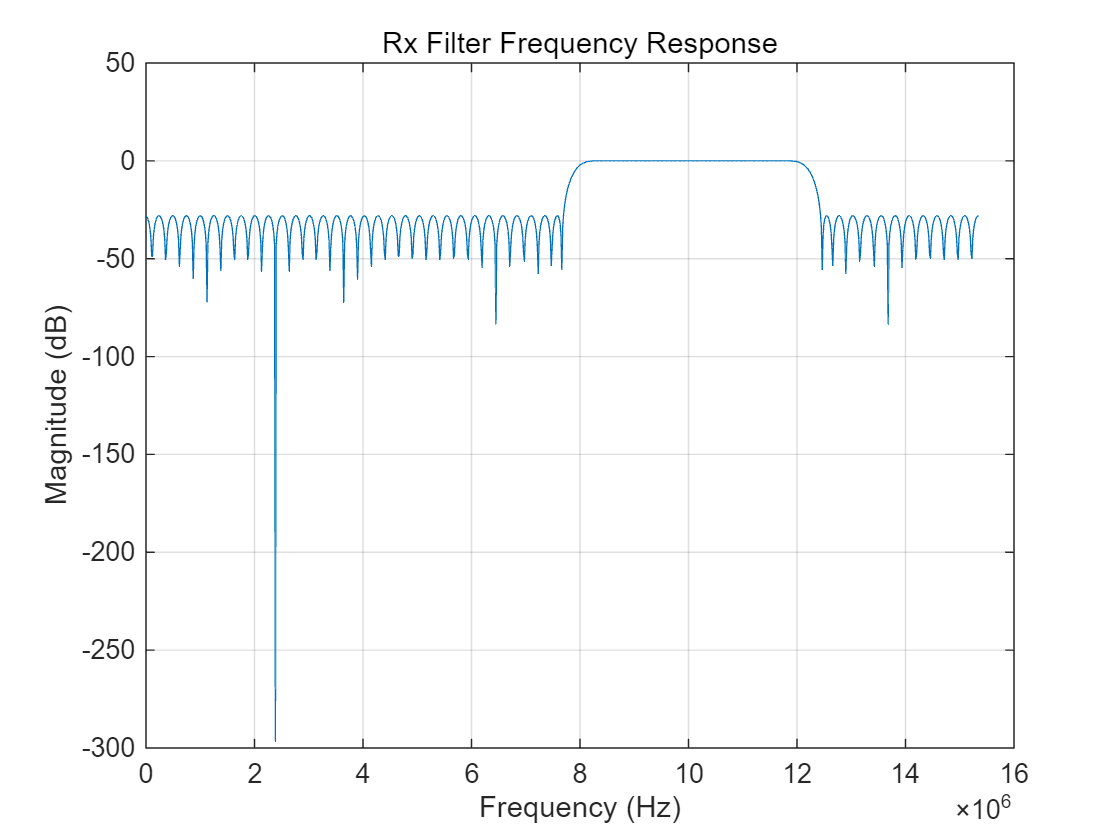

% Clear all the function data as they contain some persistent variables
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset;
close all;


errorRate_bs1 = comm.ErrorRate();
errorRate_bs2 = comm.ErrorRate();
toverflow = 0; % Receiver overflow count
rxObj = helperOFDMRxInit(sysParam);


Sync symbol found.
Estimating carrier frequency offset ........
Receiver camped.
Detected and processing frame 8
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.935886e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 8: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 9
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.938952e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 9: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 10
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.927865e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 10: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 11
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.921331e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 11: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 12
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.913349e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 12: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 13
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.918857e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 13: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 14
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.929446e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 14: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 15
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.938653e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 15: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 16
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.936506e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 16: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 17
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.922927e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 17: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 18
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.923112e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 18: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 19
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.929647e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 19: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 20
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.928400e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 20: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 21
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.926106e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 21: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 22
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.919567e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 22: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 23
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.920110e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 23: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 24
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.927672e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 24: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 25
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.929767e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 25: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 26
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.934806e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 26: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 27
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.920899e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 27: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 28
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.919990e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 28: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 29
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.928293e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 29: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

Detected and processing frame 30
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -5.930083e+03 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=1/2, and FFT Length=512
Data CRC passed
Data decoding completed
------------------------------------------


Received data in frame 30: BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmission test from BS1 message!BS1 N310 report! this is a cooperative transmiss

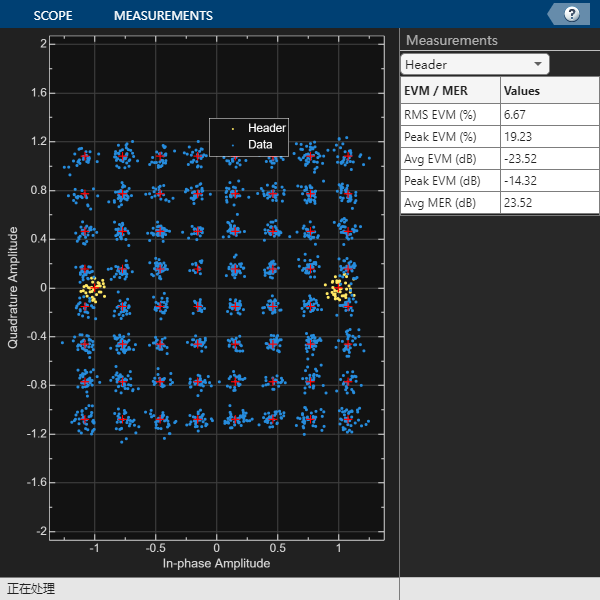

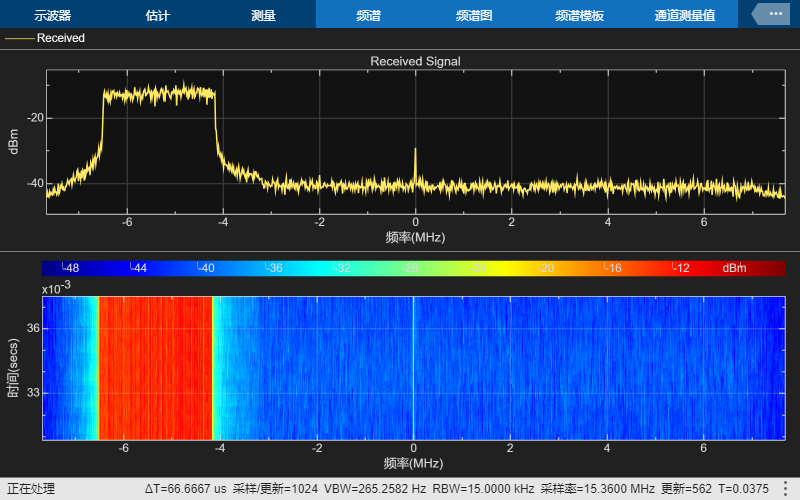

BER_bs1 = zeros(1,dataParams.numFrames);
BER_bs2 = zeros(1,dataParams.numFrames);
data_collec = [];
for frameNum = 1:dataParams.numFrames
    sysParam.frameNum = frameNum;
    if read_savedData
        rxWaveform = bbr();
        overflow = 0;
    else
        [rxWaveform, ~, overflow] = radio();
    end
    
    if save_data
        data_collec = [data_collec;rxWaveform];
    end
    toverflow = toverflow + overflow;

    % Run the receiver front-end only when there is no overflow
    if ~overflow
        rxIn = helperOFDMRxFrontEnd(rxWaveform,sysParam,rxObj);

        % Run the receiver processing
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj, timesink);
        sysParam.timingAdvance = toff;

        % Collect bit and frame error statistics
        if isConnected
            % Continuously update the bit error rate using the |comm.ErrorRate|
            % System object
            berVals_bs1 = errorRate_bs1(...
                transportBlk_bs1((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER_bs1(frameNum) = berVals_bs1(1);

            berVals_bs2 = errorRate_bs2(...
                transportBlk_bs2((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER_bs2(frameNum) = berVals_bs2(1);
            if dataParams.printData
                % As each character in the data is encoded by 7 bits, decode the received data upto last multiples of 7
                numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits),7);
                recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode),7,[]),7));
                fprintf('Received data in frame %d: %s',frameNum,recData);
            end
        end

        if isConnected && dataParams.enableScopes
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                complex(rxDiagnostics.rxConstellationData(:)));
        end

        rmsEVM_header = 0; 
        rmsEVM_data = 0; 
        merdb_header = 0;
        merdb_data = 0;

        if isConnected && dataParams.enableConst_measure
            rmsEVM_header = constellation_measure.evm_header(complex(rxDiagnostics.rxConstellationHeader(:))); 
            rmsEVM_data = constellation_measure.evm_data(complex(rxDiagnostics.rxConstellationData(:))); 
            merdb_header = constellation_measure.mer_header(complex(rxDiagnostics.rxConstellationHeader(:)));
            merdb_data = constellation_measure.mer_data(complex(rxDiagnostics.rxConstellationData(:)));
        end

        if dataParams.enableScopes
            spectrumAnalyze(rxWaveform);
        end
    end
end

% Display the mean BER value across all frames
fprintf(['Simulation complete!\n' ...
    'BS1 massage Average BER = %d \n' ...
    'BS2 massage Average BER = %d \n' ...
    '-------measurement-------\n' ...
    'Header rms EVM(%%): %.3f %% \n' ...
    'Data rms EVM(%%): %.3f %% \n' ...
    'Header MER(dB): %.3f dB \n' ...
    'Data MER(dB): %.3f dB'],mean(BER_bs1),mean(BER_bs2),rmsEVM_header, rmsEVM_data, merdb_header, merdb_data)

Simulation complete!
BS1 massage Average BER = 0 
BS2 massage Average BER = 3.009773e-01 
-------measurement-------
Header rms EVM(%): 6.671 % 
Data rms EVM(%): 6.485 % 
Header MER(dB): 23.517 dB 
Data MER(dB): 23.761 dB

% fprintf('-------measurement-------')
% fprintf('Header rms EVM(%%): %.3f %%', rmsEVM_header)
% fprintf('Data rms EVM(%%): %.3f %%', rmsEVM_data)
% fprintf('Header MER(dB): %.3f dB', merdb_header)
% fprintf('Data MER(dB): %.3f dB', merdb_data)
if save_data
    bbw = comm.BasebandFileWriter(save_filename,SampleRate=sampleRate,CenterFrequency=centerFrequency);
    bbw(data_collec);
    info(bbw)
    release(bbw)
end
if read_savedData
    release(bbr)
end
release(radio);